# Unterschiedliche Vektornormen

Wir wollen Eigenschaften verschiedener Vektornormen untersuchen. Hierzu sind zwei Aspekte insbesondere hervorzuheben:

- die Länge des Vektors 

- das Verhalten bzgl. eines Ausreißerwertes in dem Vektor

Wir betrachten die folgenden Normen

-  
$$   \|x\|_1 =\sum_{i=1}^n |x_i|$$


- 
$$\|x\|_{1,n}:=\frac{1}{n}\|x\|_1$$


- 
$$ \|x\|_2=\left(\sum_{i=1}^n |x_i|^2\right)^\frac12$$


- 
$$\|x\|_{2,n}:=\frac{1}{\sqrt{n}}\|x\|_2$$


- 
$$\|x\|_\infty= \max_{1 \leq i \leq n} |x_i|$$


Zunächst wird die Länge des zu betrachtenden Vektors vorgegeben:

n=100

n = 1000

Als Beispielvektoren wählen wir eine Linearkombination 

               $x=z+\beta e_2$, 

wobei die Komponenten $z_i$ von $z \in \mathbb{R}^n$ Realisierungen einer auf $[0,1]$ gleichverteilten Zufallsvariable sind, und $e_2$ der zweite Basisvektor   in $\mathbb{R}^n$. Der Parameter $\beta \in \mathbb{R}$ beeinflusst die Gewichtung der beiden Vektoren $z$ und  $e_2$ in der Linearkombination:

beta=0.1

beta = 10

Um die Vergleichbarkeit bei der Veränderung der Parameter $n$ und $\beta$ zu gewährleisten, wird der einmal ermittelte Zufallsvektor $z$ für ein gegebenes $n$ beibehalten.

Die Ergebnisse werden in einer Matrix festgehalten, die beim ersten Durchlauf initialisiert wird:

if exist('Erg','var')<1    %%Initialisierung 
Erg=[];
end

Bestimmung der Normen für die vorgegebenen Parameterwerte:

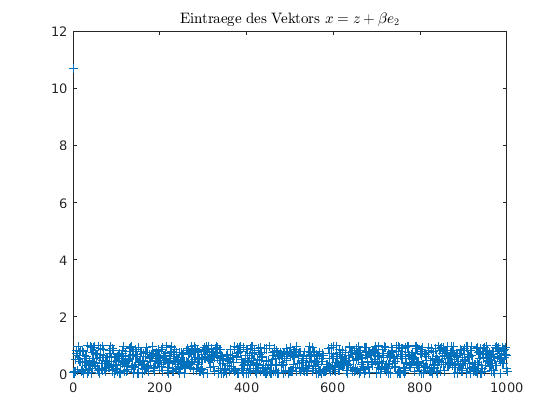

[Erg] = evaluate_params(beta,n,Erg);

Die Einträge $x_i$, $i=1,\ldots,n$, des Vektors $x=z+\beta e_2$ werden geplottet. Die verschiedenen Normen werden berechnet und in einer Tabelle dargestellt. 

# Aktivität:

Variieren Sie $n$ und $\beta$, zum Beispiel $n=100$, $\beta \in \{0.1,1,10,100\}$, oder $\beta=0.1$, $n\in \{10,100,1000\}$. 

Welche Norm  ist am wenigsten empfindlich für große Ausreißer?   

Welche Normen hängen (für diese Beispielvektoren) nicht stark  von der Dimension $n$ ab?

function [Erg] = evaluate_params(beta,n,Erg) %Funktion zur Bestimmung der Normen; Ausgabe in Tabelle
    global z;
    close all;
    if length(z) ~= n
        z = rand(n,1);
    end        
    e1=zeros(n,1);
    e1(2)=1;
    x=z+beta*e1;

    [m,~] =size(Erg);
    plot(x,'+');
    title('Eintraege des Vektors $x=z+\beta e_2$','Interpreter','latex');
    
    Erg(m+1,1) = n;
    Erg(m+1,2) = beta;
    Erg(m+1,3) = norm(x,1);
    Erg(m+1,4) = Erg(m+1,3)/n;
    Erg(m+1,5) = norm(x);
    Erg(m+1,6) = Erg(m+1,5)/sqrt(n);
    Erg(m+1,7) = norm(x,inf);
    
    height = (m+5) * 25;
    f=figure('Position',[100 200 600 height]);
    height = (m+4) * 25;
    t=uitable(f,'Data',Erg,'Position',[10 20 600 height]);
    t1=sprintf('<html>n</html>');
    t2=sprintf('<html>β</html>');
    t3=sprintf('<html>||x||<sub>1</sub></html>');
    t4=sprintf('<html>||x||<sub>1,n</sub></html>');
    t5=sprintf('<html>||x||<sub>2</sub></html>');
    t6=sprintf('<html>||x||<sub>2,n</sub></html>');
    t7=sprintf('<html>||x||<sub>∞</sub></html>');
    t.ColumnName = {t1,t2,t3,t4,t5,t6,t7};
end